# MAE 4733 - Automatic Control Systems: Final Project

Diego Colón

12-5-2020

clear all

## Bicopter Dynamics:


$$\begin{array}{l}
\ddot{h} \left(t\right)=-g+\frac{1}{M+2m}\cos \left(\theta \left(t\right)\right)F\left(t\right)\\
\ddot{z} \left(t\right)=-\frac{\mu }{M+2m}\dot{z} -\frac{1}{M+2m}\sin \left(\theta \left(t\right)\right)F\left(t\right)\\
\theta^¨ \left(t\right)=\frac{1}{2{\textrm{md}}^2 +J}\tau \left(t\right)
\end{array}$$


## Part 1

### 1.1 - State Space Model

Taking the eqautions provided in the exam can be expressed in a state space form ($x=f\left(x,u\right),y=\phi \left(x,h\right)$) , with state $x={}{\left\lbrack \begin{array}{cccccc}
h & \dot{h}  & z & \dot{z}  & \theta  & \theta^˙ 
\end{array}\right\rbrack }^T$and input $u={}{\left\lbrack \begin{array}{cc}
F & \tau 
\end{array}\right\rbrack }^T$ as:


$$\dot{x} =f\left(x,u\right)=\left\lbrack \begin{array}{c}
\dot{h} \\
\frac{\mathrm{Fcos}\left(\theta \right)}{M+2m}-g\\
\dot{z} \\
-\frac{\mu \dot{z} }{M+2m}-\frac{\mathrm{Fsin}\left(\theta \right)}{M+2m}\\
\theta^˙ \\
\frac{\tau }{2{\mathrm{md}}^2 +J}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \\
\frac{u_1 \mathrm{cos}\left(x_5 \right)}{M+2m}-g\\
x_4 \\
-\frac{\mu x_4 }{M+2m}-\frac{u_1 \mathrm{sin}\left(x_5 \right)}{M+2m}\\
x_6 \\
\frac{u_2 }{2{\mathrm{md}}^2 +J}
\end{array}\right\rbrack$$



$$y=\phi \left(x,u\right)=\left\lbrack \begin{array}{c}
h\\
z\\
\theta 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_3 \\
x_5 
\end{array}\right\rbrack$$


### 1.2 - Equilibium Trajectory

In order to create controllers, with the techniques learned in class, it is required to linearize the dynamics about an equilibrium trajectory. Equilibrium trajectories and corresponding measurementsare defined as:


$$\left(x^{\ast } \left(t\right),u^{\ast } \left(t\right)\right)\owns \dot{x} \left(t\right)=f\left(x^{\ast } \left(t\right),u^{\ast } \left(t\right)\right)=0\;\forall \;t\ge 0$$



$$y^{\ast } \left(t\right)=\phi \left(x^{\ast } \left(t\right),u^{\ast } \left(t\right)\right)$$


%% Create all the system variables
syms s 
syms h h_dot h_ddot z z_dot z_ddot theta theta_dot theta_ddot 
syms g M m mu d J
syms F tau

%% Create symbols and values array for substitution
k = [g; M; m;  mu; d; J];
k_val = [9.81; 1; 0.25;  0.1; 0.3; 0.0042];

%% Write the VTOL Dynamics
h_ddot = -g +(cos(theta)*F)/(M+2*m);
z_ddot = -(mu*z_dot)/(M+2*m) - (sin(theta)*F)/(M+2*m);
theta_ddot = tau/(2*m*d^2 + J);

%% Create x, u, f(x,u) and h(x,u)
x = [h; h_dot; z; z_dot; theta; theta_dot]

$$x = \left(\begin{array}{c} h\\ \dot{h}\\ z\\ \dot{z}\\ \theta \\ \dot{\theta } \end{array}\right)$$

u = [F;tau]

$$u = \left(\begin{array}{c} F\\ \tau \end{array}\right)$$

process = [h_dot; h_ddot; z_dot; z_ddot; theta_dot; theta_ddot]

$$process = \left(\begin{array}{c} \dot{h}\\ \frac{F\,\cos\left(\theta \right)}{M+2\,m}-g\\ \dot{z}\\ -\frac{\mu \,\dot{z}}{M+2\,m}-\frac{F\,\sin\left(\theta \right)}{M+2\,m}\\ \dot{\theta }\\ \frac{\tau }{2\,m\,d^{2}+J} \end{array}\right)$$

meas = [h; z; theta]

$$meas = \left(\begin{array}{c} h\\ z\\ \theta \end{array}\right)$$


%% Solve for trajectory to linearize about
S = solve(process,[x;u]);
x_star = [S.h+10;S.h_dot;S.z;S.z_dot;S.theta;S.theta_dot]

$$x\_star = \left(\begin{array}{c} 10\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

u_star = [S.F;S.tau]

$$u\_star = \left(\begin{array}{c} g\,\left(M+2\,m\right)\\ 0 \end{array}\right)$$

y_star= [S.h+10;S.z;S.theta]

$$y\_star = \left(\begin{array}{c} 10\\ 0\\ 0 \end{array}\right)$$

### 1.3 - Linearize Dynamics

Once a equilibrium trajectory has been found, the dynamics must be linearized about them to express them in the form


$$\begin{array}{l}
{}{\dot{x} }_{\delta }=A{}x_{\delta }+B{}u_{\delta }\\
{}y_{\delta }=C{}x_{\delta }+D{}u_{\delta }
\end{array}$$


A = simplify(subs(jacobian(process,x),[x;u],[x_star;u_star]))

$$A = \left(\begin{array}{cccccc} 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & -\frac{\mu }{M+2\,m} & -g & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

B = simplify(subs(jacobian(process,u),[x;u],[x_star;u_star]))

$$B = \left(\begin{array}{cc} 0 & 0\\ \frac{1}{M+2\,m} & 0\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 0 & \frac{1}{2\,m\,d^{2}+J} \end{array}\right)$$

C = simplify(subs(jacobian(meas,x),[x;u],[x_star;u_star]))

$$C = \left(\begin{array}{cccccc} 1 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0 \end{array}\right)$$

D = simplify(subs(jacobian(meas,u),[x;u],[x_star;u_star]))

$$D = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

x_star = subs(x_star,k,k_val);
u_star = subs(u_star,k,k_val);

### 1.4 - MIMO TF

Since bicopter is a multi-input, multi-output system, the system can be written as a MIMO tranfer function. In this case that transfer function is of the form


$$\left\lbrack \begin{array}{c}
H\left(s\right)\\
Z\left(s\right)\\
\Theta \left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
{}G_{\mathrm{HF}}\left(s\right) & {}G_{FT}\left(s\right)\\
{}G_{\mathrm{ZF}}\left(s\right) & {}G_{ZT}\left(s\right)\\
{}G_{\Theta F}\left(s\right) & {}G_{\Theta T}\left(s\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
F\left(s\right)\\
T\left(s\right)
\end{array}\right\rbrack$$


G = collect(simplify(C*inv(s*eye(size(A, 1)) - A)*B + D),s)

$$G = \left(\begin{array}{cc} \frac{1}{\left(M+2\,m\right)\,s^{2}} & 0\\ 0 & \frac{-M\,g-2\,g\,m}{\left(4\,d^{2}\,m^{2}+2\,M\,d^{2}\,m+2\,J\,m+J\,M\right)\,s^{4}+\left(2\,m\,\mu \,d^{2}+J\,\mu \right)\,s^{3}}\\ 0 & \frac{1}{\left(2\,m\,d^{2}+J\right)\,s^{2}} \end{array}\right)$$

### 1.5 - Relevant Transfer Functions

Taking the nonzero transfer functions out of the MIMO transfer function

G_HF = collect(simplify(subs(G(1,1),k,k_val)),s)

$$G\_HF = \frac{2}{3\,s^{2}}$$

G_ZT = collect(simplify(subs(G(2,2),k,k_val)),s)

$$G\_ZT = -\frac{122625}{615\,s^{4}+41\,s^{3}}$$

G_ThetaT = collect(simplify(subs(G(3,2),k,k_val)),s)

$$G\_ThetaT = \frac{2500}{123\,s^{2}}$$

### 1.6 - Missing TF

Given the nature of the linearized dynimcs and that we would like to implement a outer-inner loop architecture, it is required to know the relationship between $Z$ and $\Theta$.


$$G_{Z\Theta } \left(s\right)=\frac{G_{ZT} \left(s\right)}{G_{\Theta T} \left(s\right)}$$


G_ZTheta = collect(simplify(G_ZT/G_ThetaT),s)

$$G\_ZTheta = -\frac{2943}{300\,s^{2}+20\,s}$$

### 1.7 - Controller Architecture

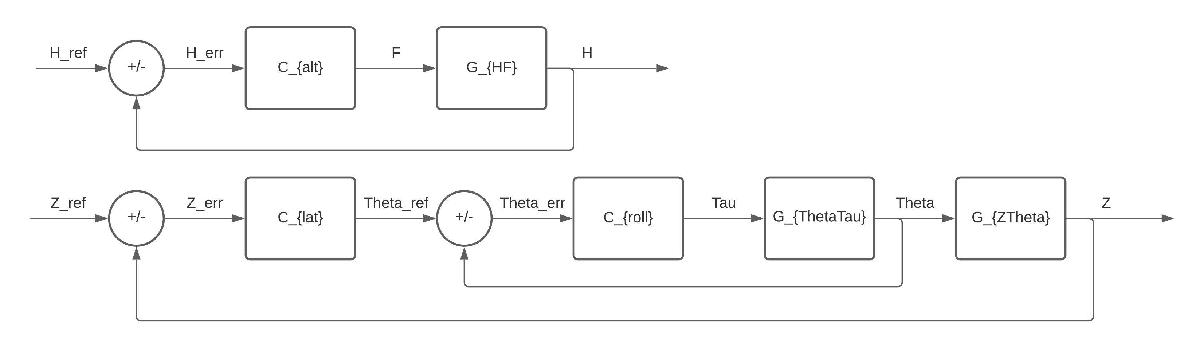

### 1.8 - Altitude Controller Design (Pole Placement)

syms Kp Kd Ki
Cp1 = Kp + Kd*s;
CL1 = collect(simplify((G_HF*Cp1)/(1 + G_HF*Cp1)),s)

$$CL1 = \frac{\left(2\,\mathrm{Kd}\right)\,s+2\,\mathrm{Kp}}{3\,s^{2}+\left(2\,\mathrm{Kd}\right)\,s+2\,\mathrm{Kp}}$$

[Num,Den] = numden(G_HF);
G_HF= tf(sym2poly(Num),sym2poly(Den));

t_r = 2;
zeta = 0.707;

omega_n = (2.16*zeta+0.6)/t_r;
Kp_alt = (3/2)*omega_n^2;
Kd_alt = 3*zeta*omega_n;
C_alt = tf([Kd_alt,Kp_alt,0],[1,0])

C_alt =
 
  2.256 s^2 + 1.697 s
  -------------------
           s
 
Continuous-time transfer function.



CL_alt = minreal(feedback(C_alt*G_HF,1))

CL_alt =
 
     1.504 s + 1.131
  ---------------------
  s^2 + 1.504 s + 1.131
 
Continuous-time transfer function.



stepinfo(CL_alt)

ans = struct with fields:
        RiseTime: 0.7956
    SettlingTime: 4.6010
     SettlingMin: 0.9331
     SettlingMax: 1.2079
       Overshoot: 20.7910
      Undershoot: 0
            Peak: 1.2079
        PeakTime: 2.0823


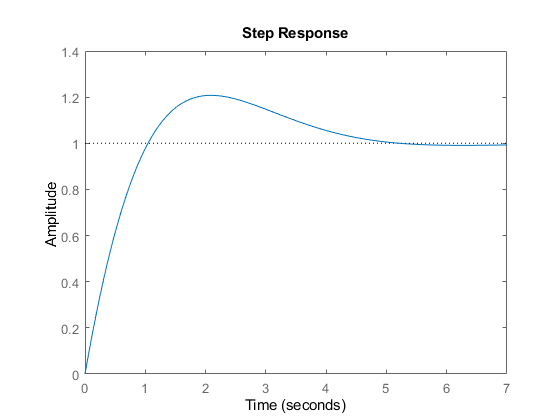

step(CL_alt)

isstable(CL_alt)

ans = logical
   1


% System did not meet specificaltions, redesign iterations began. 
% Final Design:

zeta = 0.8;
omega_n = 1;
Kp_alt = (3/2)*omega_n^2;
Kd_alt = (3/2)*(2*zeta*omega_n);
C_alt = tf([Kd_alt,Kp_alt,0],[1,0])

C_alt =
 
  2.4 s^2 + 1.5 s
  ---------------
         s
 
Continuous-time transfer function.



CL_alt = minreal(feedback(C_alt*G_HF,1))

CL_alt =
 
     1.6 s + 1
  ---------------
  s^2 + 1.6 s + 1
 
Continuous-time transfer function.



stepinfo(CL_alt)

ans = struct with fields:
        RiseTime: 0.8068
    SettlingTime: 5.0537
     SettlingMin: 0.9276
     SettlingMax: 1.1798
       Overshoot: 17.9763
      Undershoot: 0
            Peak: 1.1798
        PeakTime: 2.1299


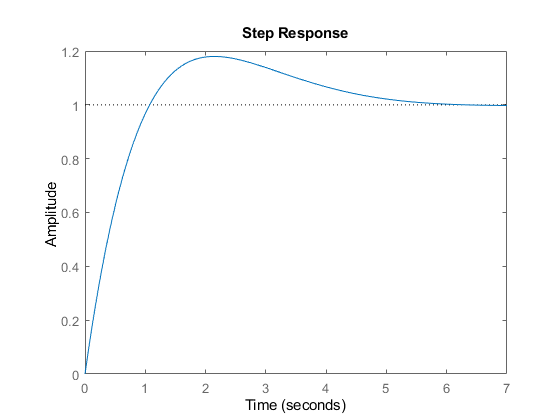

step(CL_alt)

isstable(CL_alt)

ans = logical
   1


### 1.9.1 - Inner Loop Controller Design (Pole Placement)

syms Kp Kd Ki
Cp2 = Kp + Kd*s;
CL2 = collect(simplify((G_ThetaT*Cp2)/(1 + G_ThetaT*Cp2)),s)

$$CL2 = \frac{\left(2500\,\mathrm{Kd}\right)\,s+2500\,\mathrm{Kp}}{123\,s^{2}+\left(2500\,\mathrm{Kd}\right)\,s+2500\,\mathrm{Kp}}$$

[Num,Den] = numden(G_ThetaT);
G_ThetaTau = tf(sym2poly(Num),sym2poly(Den))

G_ThetaTau =
 
   2500
  -------
  123 s^2
 
Continuous-time transfer function.



t_r = 0.3;
M = 5;

zeta = abs(log(M/100))/sqrt(pi^2 + abs((log(M/100))^2));
omega_n = 1.8/t_r;

Kp_roll = (123/2500)*(omega_n^2);
Kd_roll = (123/2500)*(2*zeta*omega_n);
C_inner = tf([Kd_roll,Kp_roll,0],[1,0])

C_inner =
 
  0.4074 s^2 + 1.771 s
  --------------------
           s
 
Continuous-time transfer function.



CL_inner = minreal(feedback(C_inner*G_ThetaTau,1))

CL_inner =
 
     8.281 s + 36
  ------------------
  s^2 + 8.281 s + 36
 
Continuous-time transfer function.



stepinfo(CL_inner)

ans = struct with fields:
        RiseTime: 0.1423
    SettlingTime: 0.8111
     SettlingMin: 0.9038
     SettlingMax: 1.2136
       Overshoot: 21.3587
      Undershoot: 0
            Peak: 1.2136
        PeakTime: 0.3781


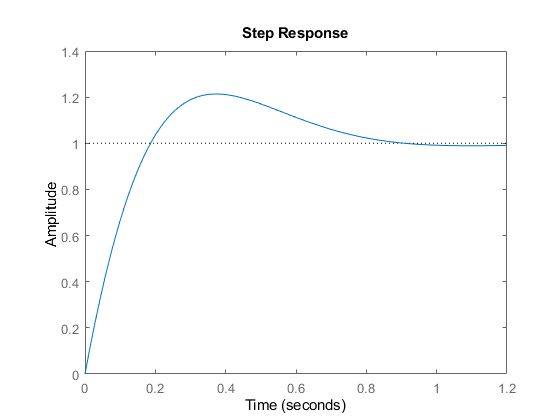

step(CL_inner)

isstable(CL_inner)

ans = logical
   1


% System did not meet specificaltions, redesign iterations began. 
% Final Design:

a = -0.25;
b = -15;

Kp_roll = (a*b)/(2500/123);
Kd_roll = (-a-b)/(2500/123);
C_inner = tf([Kd_roll,Kp_roll,0],[1,0])

C_inner =
 
  0.7503 s^2 + 0.1845 s
  ---------------------
            s
 
Continuous-time transfer function.



CL_inner = minreal(feedback(C_inner*G_ThetaTau,1))

CL_inner =
 
     15.25 s + 3.75
  --------------------
  s^2 + 15.25 s + 3.75
 
Continuous-time transfer function.



stepinfo(CL_inner)

ans = struct with fields:
        RiseTime: 0.1376
    SettlingTime: 0.2227
     SettlingMin: 0.9048
     SettlingMax: 1.0145
       Overshoot: 1.4507
      Undershoot: 0
            Peak: 1.0145
        PeakTime: 0.5557


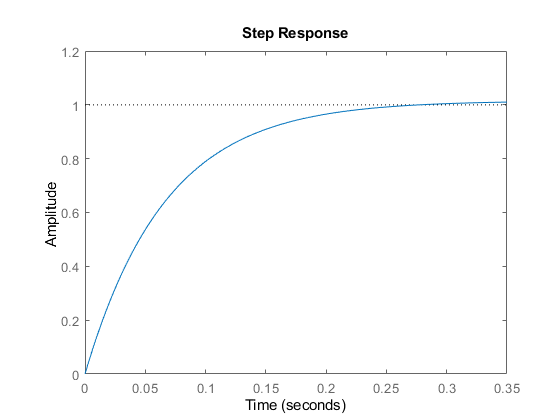

step(CL_inner)

isstable(CL_inner)

ans = logical
   1


### 1.9.2 - Outer Loop Controller Design (Pole Placement)

syms Kp Kd Ki
Cp3 = Kp + Kd*s;
CL3 = collect(simplify((dcgain(CL_inner)*G_ZTheta*Cp1)/(1 + dcgain(CL_inner)*G_ZTheta*Cp1)),s)

$$CL3 = \frac{\left(2943\,\mathrm{Kd}\right)\,s+2943\,\mathrm{Kp}}{-300\,s^{2}+\left(2943\,\mathrm{Kd}-20\right)\,s+2943\,\mathrm{Kp}}$$

[Num,Den] = numden(G_ZTheta);
G_ZTheta = tf(dcgain(CL_inner)*sym2poly(Num),sym2poly(Den));

t_r = 3;
t_s = 8;

Kp_pos = (-300/2943)*(1.8/t_r)^2;
Kd_pos = (-300/2943)*(8/t_s) + 20/(-2943);
C_outer = tf([Kd_pos,Kp_pos,0],[1,0])

C_outer =
 
  -0.1087 s^2 - 0.0367 s
  ----------------------
            s
 
Continuous-time transfer function.



CL_outer = minreal(feedback(C_outer*G_ZTheta,1))

CL_outer =
 
     1.067 s + 0.36
  --------------------
  s^2 + 1.133 s + 0.36
 
Continuous-time transfer function.



stepinfo(CL_outer)

ans = struct with fields:
        RiseTime: 1.3778
    SettlingTime: 8.6187
     SettlingMin: 0.9192
     SettlingMax: 1.1163
       Overshoot: 11.6250
      Undershoot: 0
            Peak: 1.1163
        PeakTime: 3.5758


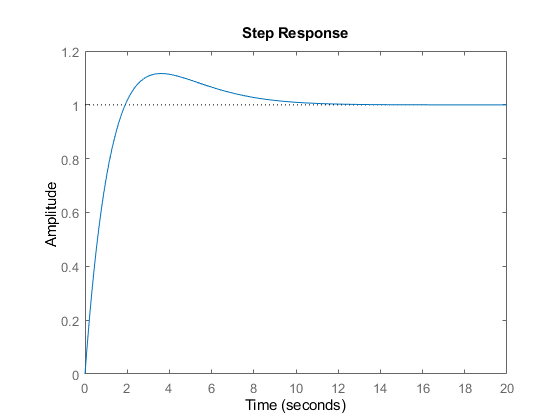

step(CL_outer)

isstable(CL_outer)

ans = logical
   1


% System did not meet specificaltions, redesign iterations began. 
% Final Design:

Kp_pos = -0.002;
Kd_pos = -1;
C_outer = tf([Kd_pos,Kp_pos,0],[1,0])

C_outer =
 
  -s^2 - 0.002 s
  --------------
        s
 
Continuous-time transfer function.



CL_outer = minreal(feedback(C_outer*G_ZTheta,1))

CL_outer =
 
     9.81 s + 0.01962
  -----------------------
  s^2 + 9.877 s + 0.01962
 
Continuous-time transfer function.



stepinfo(CL_outer)

ans = struct with fields:
        RiseTime: 0.2286
    SettlingTime: 0.4357
     SettlingMin: 0.9028
     SettlingMax: 0.9934
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9934
        PeakTime: 1.0680


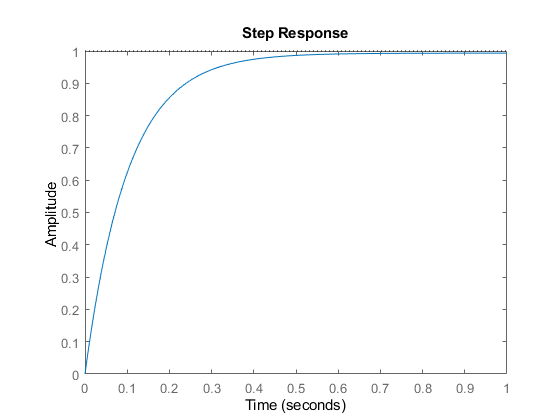

step(CL_outer)

isstable(CL_outer)

ans = logical
   1


### 1.10 - Linearized Simulation

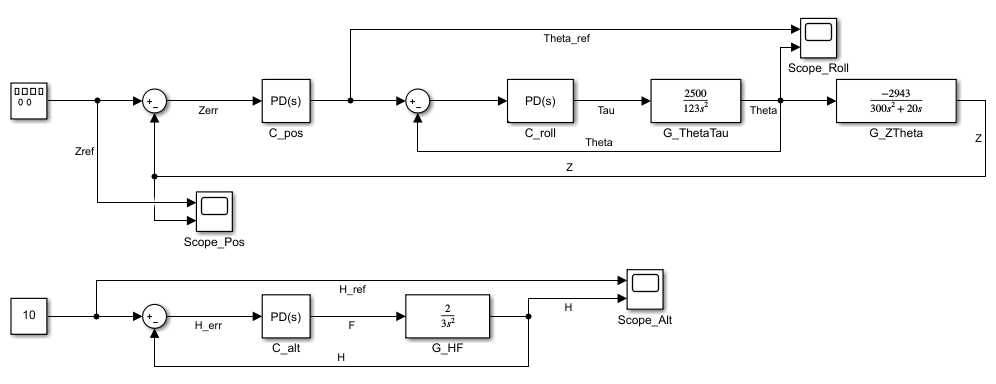

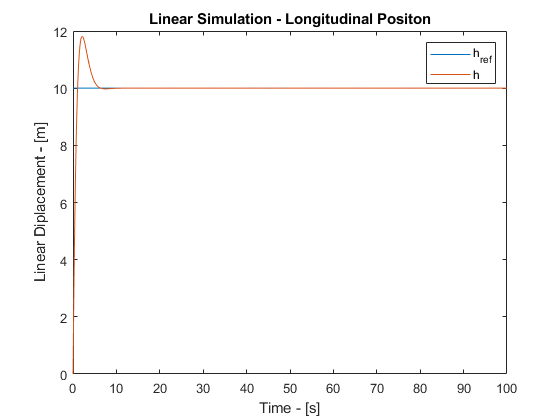

LS1 = sim('Part1_linsim',100);

plot(LS1.Alt.time,LS1.Alt.signals(1).values)
hold on
plot(LS1.Alt.time,LS1.Alt.signals(2).values)
hold off
title("Linear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

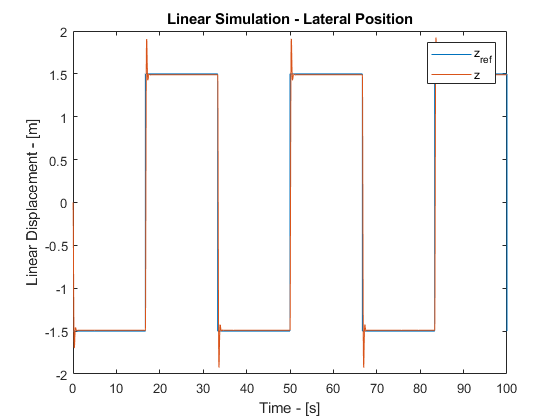

plot(LS1.Pos.time,LS1.Pos.signals(1).values)
hold on
plot(LS1.Pos.time,LS1.Pos.signals(2).values)
hold off
title("Linear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 1.11 - Nonlinear Simulation

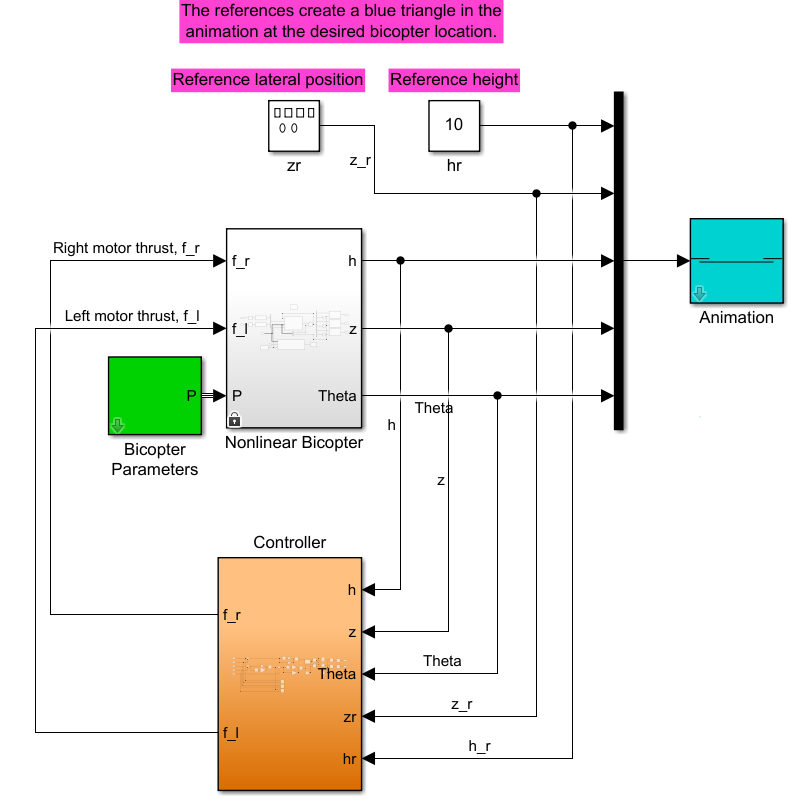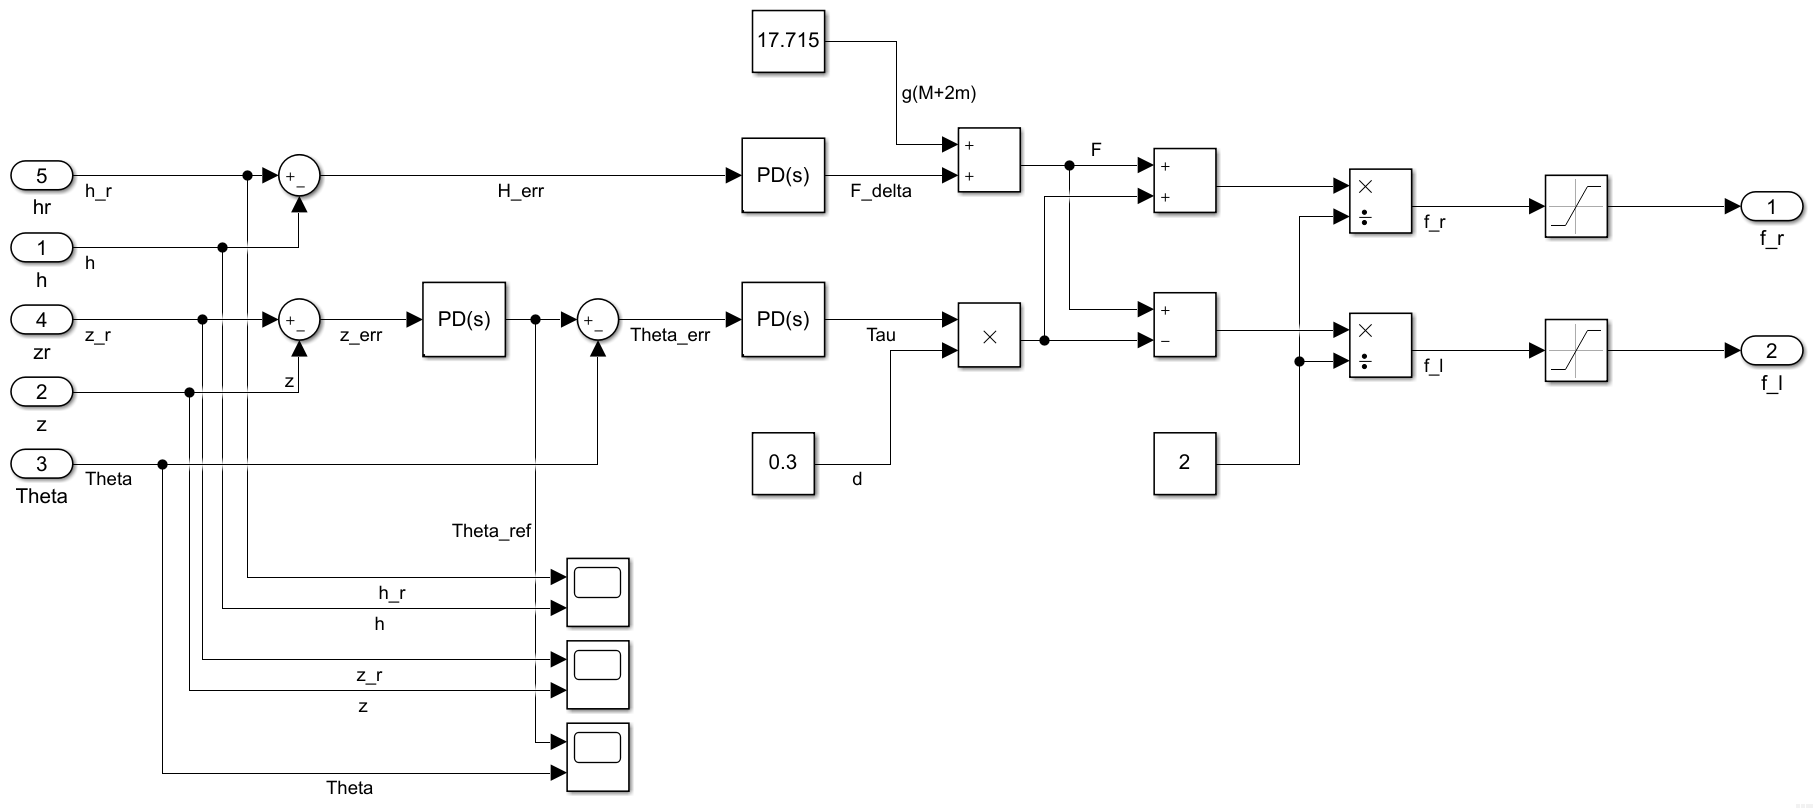

wind = 0;
variaciones = 0;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

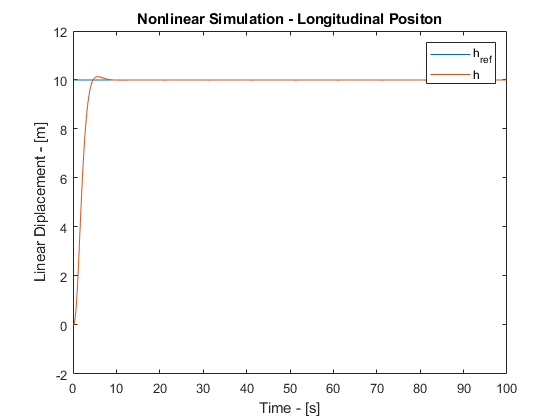

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

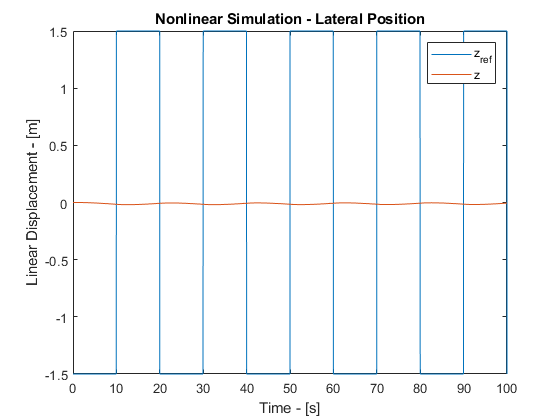

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

As it can be seen above, the Nonlinear simulation is unstable despite the linear simulation being stable. To solve this, the Linear controller gains were used as a starting point for tuning the controllers used in the nonlinear simulation. The final gains used are the following

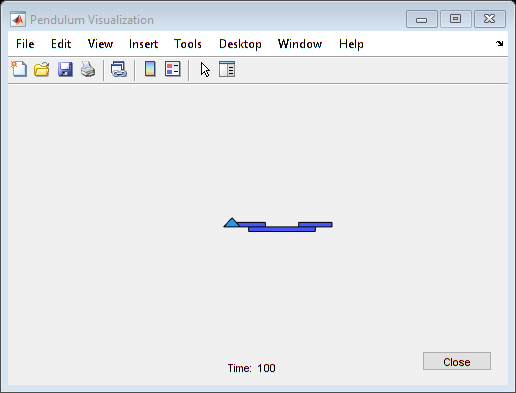

Kp_alt = 50;
Kd_alt = 100;

Kp_roll = 10;
Kd_roll = 10;

Kp_pos = -2.5;
Kd_pos = -1.25; 

wind = 0;
variaciones = 0;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

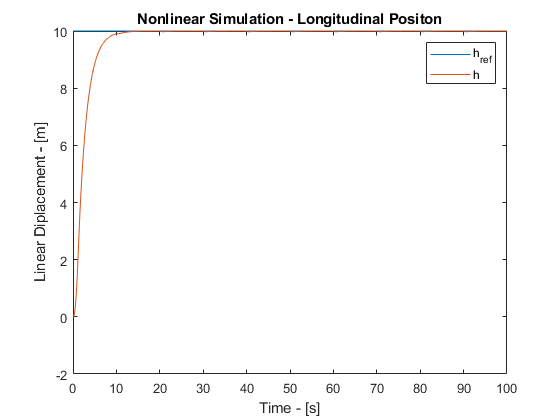

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

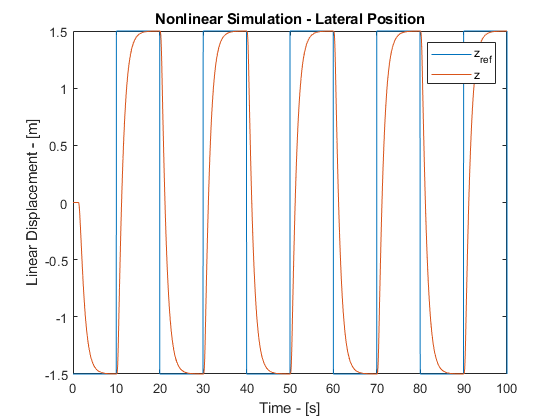

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 1.12 - Simulation Comparison

The controllers in the linear simulation are ableto track the reference trajectories with some overshoot. The same controllers when implemented in the nonlinear simulation do not track the lateral reference properly. This was expected because the controller was designed for a linearized system. The controllers had to be modified to track the lateral trajectory properly. After this modification, the system was able to track the reference trajectories properly.

### 1.13 - Addition of Noise 

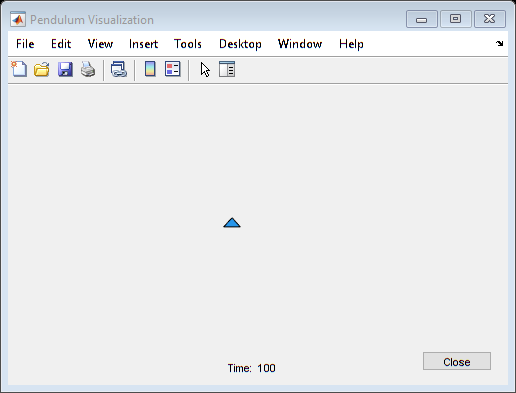

wind = 0;
variaciones = 0;
noise = 1e-6;
NLS1 = sim('Part1_planarBicopter');

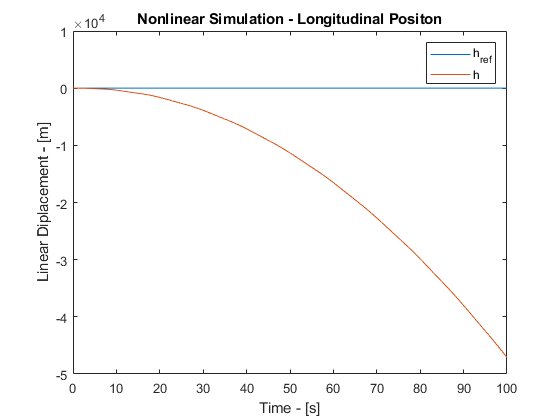

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

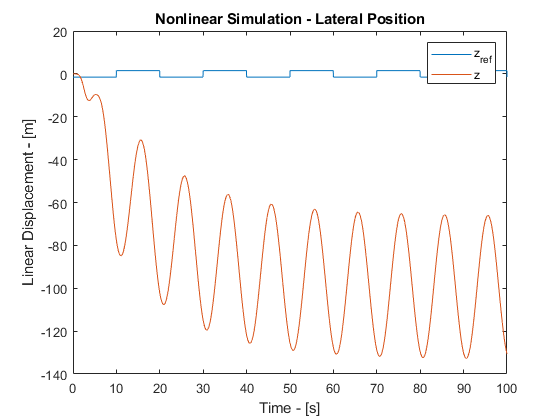

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 1.14 - Parameter Variations

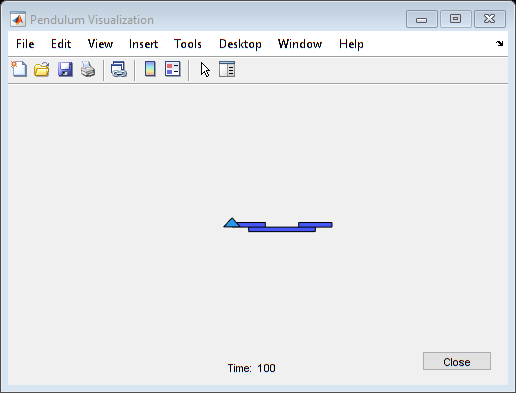

wind = 0;
variaciones = 20;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

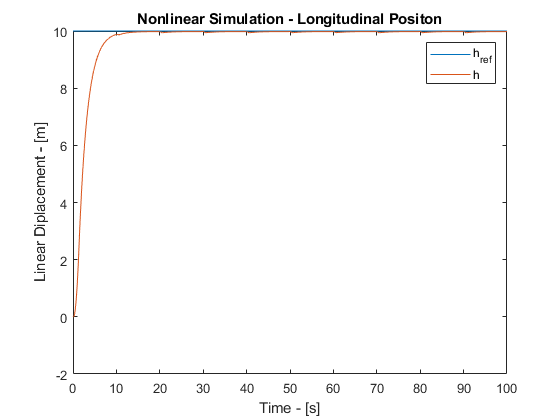

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

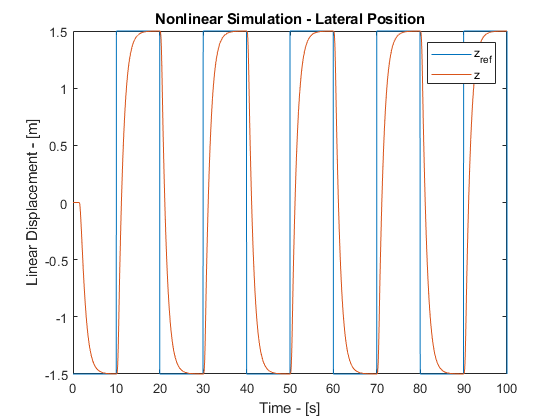

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 1.15 - Addition of Wind

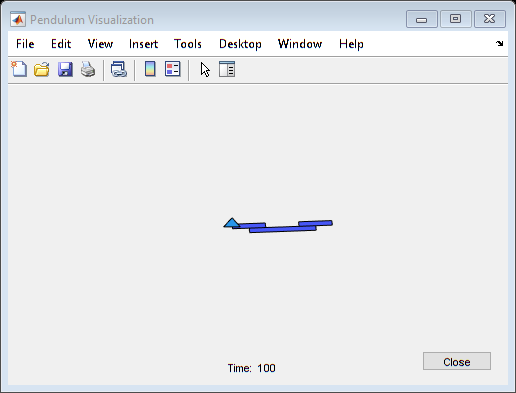

wind = 1;
variaciones = 0;
noise = 0;
NLS1 = sim('Part1_planarBicopter');

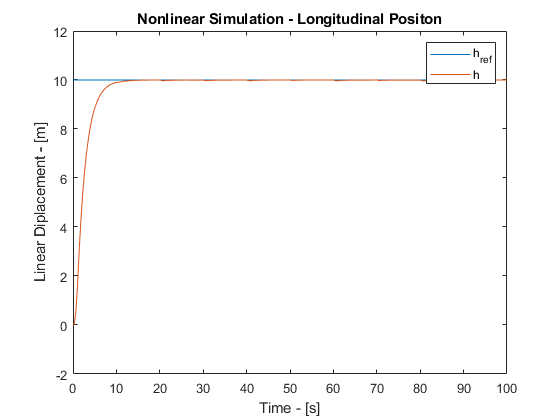

plot(NLS1.Alt.time,NLS1.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

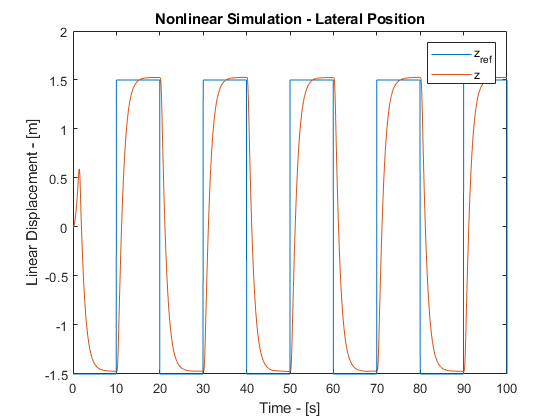

plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

## Part 2

### 2.1 - Longitudinal (Loop Shaping)

Design a controller that generates linearized thrust commands and satisfies the following constraints:

- 
$$\omega_B \le 2\;\frac{\textrm{rad}}{s}$$


- 
$$\epsilon_w \ge 0\ldotp 1\;\forall \;\omega_w \le 0\ldotp 01\;\frac{\textrm{rad}}{s}\;$$


- 
$$\epsilon_{\textrm{no}} \ge 0\ldotp 0005\;\forall \;\omega_{\textrm{no}} \ge 100\;\frac{\textrm{rad}}{s}$$


- 
$$\textrm{PM}\ge \frac{\pi }{3}\;\textrm{rad}$$


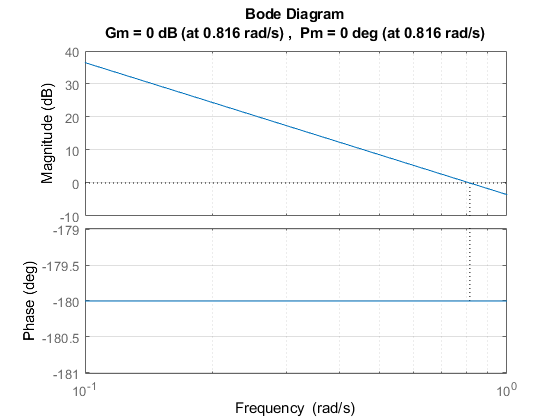

omega_w = 0.01;
mag_w = 20*log10(1/0.1);
omega_no = 100;
mag_no = 20*log10(0.0005);
w = [omega_w omega_no];


C_alt2 = 1;
margin(C_alt2*G_HF),grid

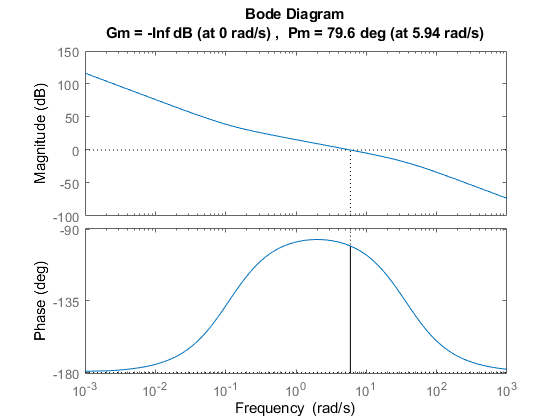


phi_lead = -80;
omega_lead = 2;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
CLead = tf([M, omega_lead*sqrt(M)],[1, omega_lead*sqrt(M)]);
C_alt2 = C_alt2 * CLead;
margin(C_alt2*G_HF),

[mag, phase, wout]=bode(C_alt2*G_HF,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


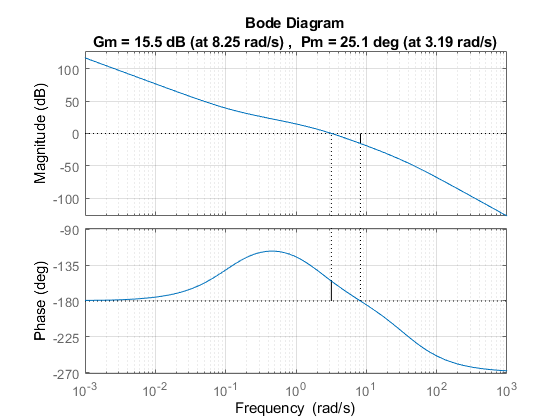

if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

LPF = tf([2],[1,2]);
C_alt2 = C_alt2 * LPF;
margin(C_alt2*G_HF),grid;

[mag, phase, wout]=bode(C_alt2*G_HF,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met


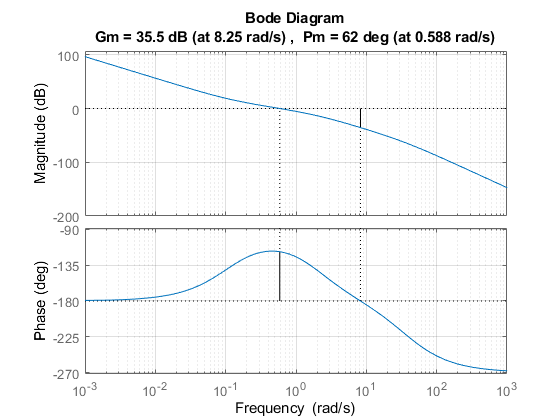


P = 0.1;
C_alt2 = C_alt2 * P;
margin(C_alt2*G_HF),grid

[mag, phase, wout]=bode(C_alt2*G_HF,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met


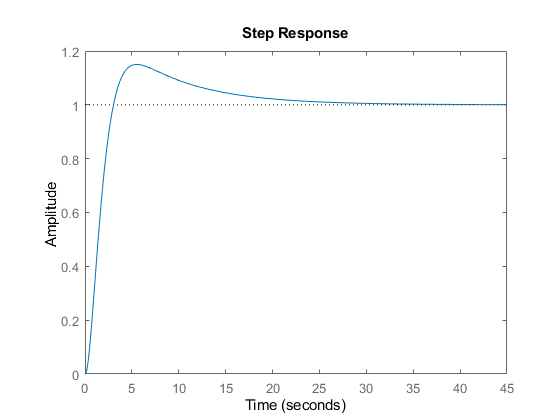


CL_alt2 = minreal(feedback(C_alt2*G_HF,1));
step(CL_alt2)

stepinfo(CL_alt2)

ans = struct with fields:
        RiseTime: 2.0555
    SettlingTime: 20.6869
     SettlingMin: 0.9056
     SettlingMax: 1.1499
       Overshoot: 14.9942
      Undershoot: 0
            Peak: 1.1499
        PeakTime: 5.5059


isstable(CL_alt2)

ans = logical
   1


### 2.2.1 - Inner Loop

Design an inner loop controller that satisfies the following constraints:

- 
$$\omega_B \ge 10\;\frac{\mathrm{rad}}{s}$$


- 
$$\epsilon_{\mathrm{no}} \ge 0\ldotp 0001\;\forall \;\omega_{\mathrm{no}} \ge 1000\;\frac{\mathrm{rad}}{s}$$


- 
$$\mathrm{PM}\ge \frac{\pi }{3}\;\mathrm{rad}$$


omega_no = 1000;
mag_no = 20*log10(0.0001);
w = [omega_no];

C_roll2 = 1

C_roll2 = 1

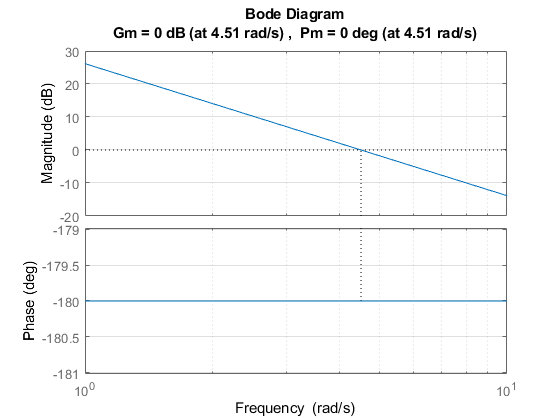

margin(C_roll2*G_ThetaTau),grid

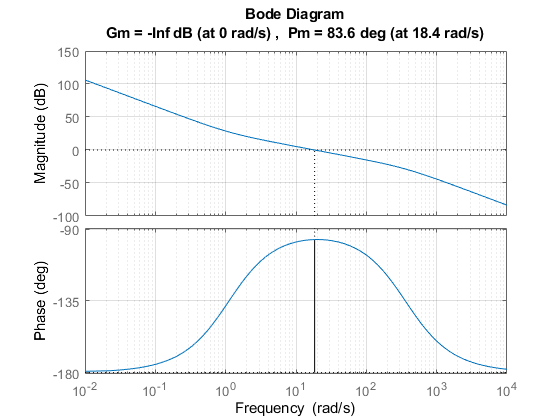



phi_lead = -80;
omega_p = 20;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
C_lead = tf([M,omega_p*sqrt(M)],[1,omega_p*sqrt(M)]);
C_roll2 = C_roll2 * C_lead;
margin(C_roll2*G_ThetaTau),grid

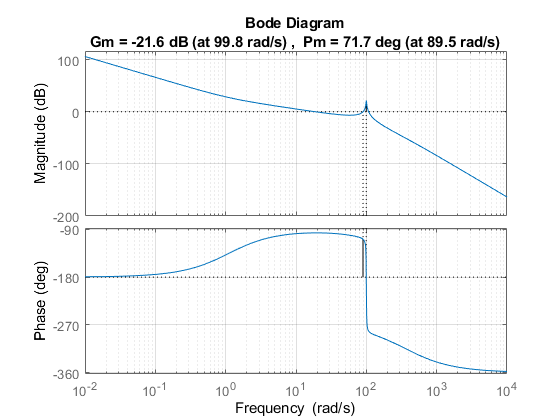

[mag, phase, wout]=bode(C_roll2*G_ThetaTau,w);
if 20*log10(mag) < mag_no
    disp("Noise met")
end

omega_c = 10000;
LPF = tf([omega_c],[1, sqrt(2), omega_c]);
C_roll2 = C_roll2 * LPF;
margin(C_roll2*G_ThetaTau),grid

[mag, phase, wout]=bode(C_roll2*G_ThetaTau,w);
if 20*log10(mag) < mag_no
    disp("Noise met")
end

Noise met



CL_roll2 = minreal(feedback(C_roll2*G_HF,1))

CL_roll2 =
 
                          2.175e06 s + 2.408e06
  ---------------------------------------------------------------------
  s^5 + 362.7 s^4 + 1.051e04 s^3 + 3.613e06 s^2 + 2.175e06 s + 2.408e06
 
Continuous-time transfer function.



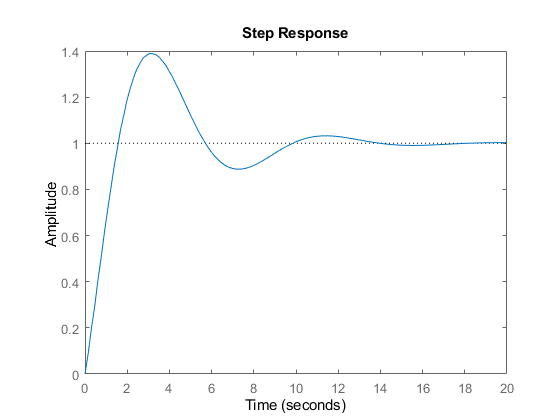

step(CL_roll2)

stepinfo(CL_roll2)

ans = struct with fields:
        RiseTime: 1.2149
    SettlingTime: 12.6676
     SettlingMin: 0.8878
     SettlingMax: 1.3900
       Overshoot: 39.0034
      Undershoot: 0
            Peak: 1.3900
        PeakTime: 3.0637


isstable(CL_roll2)

ans = logical
   1


### 2.2.2 - Outer Loop

Design an outer loop controller that satisfies the following constraints:

- 
$$\omega_B \le 1\;\frac{\mathrm{rad}}{s}$$


- 
$$\epsilon_w \ge 0\ldotp 1\;\forall \;\omega_w \le 0\ldotp 001\frac{\mathrm{rad}}{s}\;$$


- 
$$\epsilon_{\mathrm{no}} \le 0\ldotp 0001\;\forall \;\omega_{\mathrm{no}} \ge 100\;\frac{\mathrm{rad}}{s}$$


- 
$$\mathrm{PM}\ge \frac{\pi }{4}\;\mathrm{rad}$$


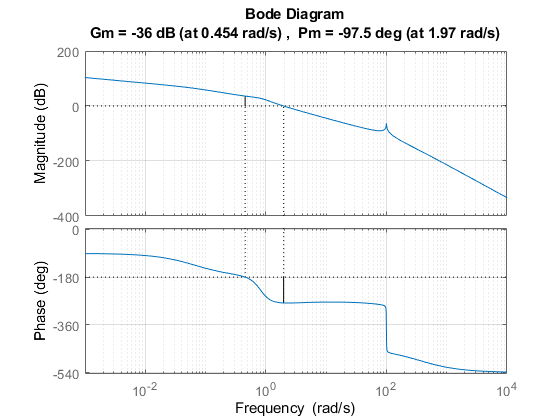

omega_w = 0.01;
mag_w = 20*log10(1/0.1);
omega_no = 100;
mag_no = 20*log10(0.0001);
w = [omega_w omega_no];

C_pos2 = -1;
margin(C_pos2*CL_roll2*G_ZTheta),grid

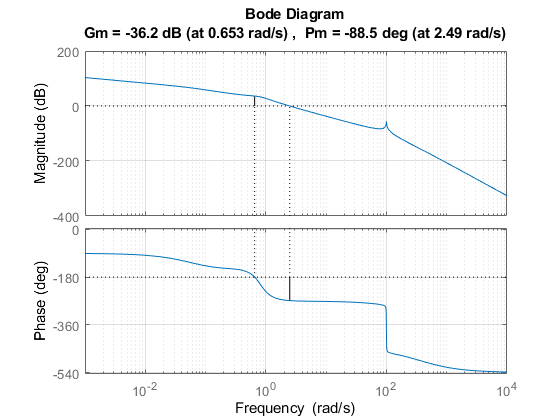



phi_lead = -75;
omega_p = 0.5;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
C_lead = tf([M,omega_p*sqrt(M)],[1,omega_p*sqrt(M)]);
C_pos2 = C_pos2 * C_lead;
margin(C_pos2*CL_roll2*G_ZTheta),grid

[mag, phase, wout]=bode(C_pos2*CL_roll2*G_ZTheta,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


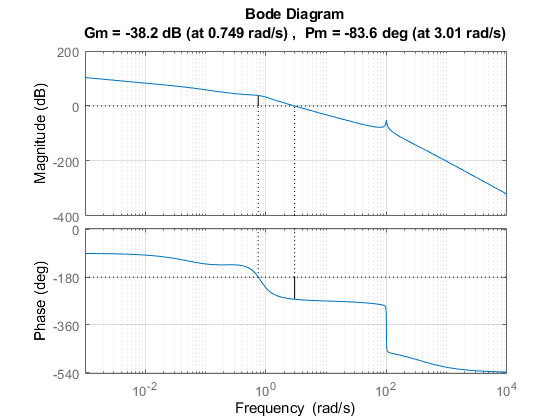

if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

phi_lead = -60;
omega_p = 0.5;
M = (1 + sin(phi_lead))/(1 - sin(phi_lead));
C_lead = tf([M,omega_p*sqrt(M)],[1,omega_p*sqrt(M)]);
C_pos2 = C_pos2 * C_lead;
margin(C_pos2*CL_roll2*G_ZTheta),grid

[mag, phase, wout]=bode(C_pos2*CL_roll2*G_ZTheta,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


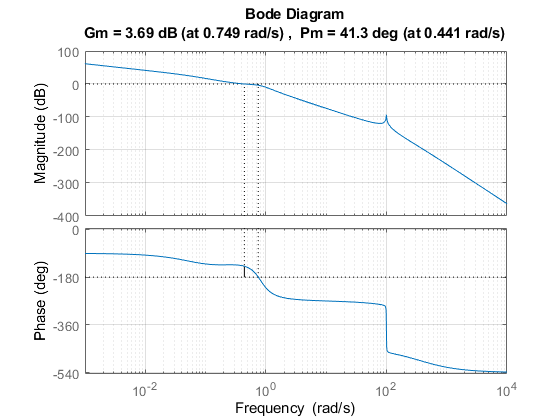

if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

P = 0.008;
C_pos2 = C_pos2 * P;
margin(C_pos2*CL_roll2*G_ZTheta),grid

[mag, phase, wout]=bode(C_pos2*CL_roll2*G_ZTheta,w);
if 20*log10(mag(1)) > mag_w
    disp("Disturbances met")
end

Disturbances met


if 20*log10(mag(2)) < mag_no
    disp("Noise met")
end

Noise met




CL_pos2 = minreal(feedback(C_pos2*CL_roll2*G_ZTheta,1))

CL_pos2 =
 
                                         7.263e05 s^3 + 1.31e06 s^2 + 6.486e05 s + 9.747e04
  --------------------------------------------------------------------------------------------------------------------------------
  s^9 + 364.2 s^8 + 1.106e04 s^7 + 3.629e06 s^6 + 7.616e06 s^5 + 7.89e06 s^4 + 5.804e06 s^3 + 2.858e06 s^2 + 7.314e05 s + 9.747e04
 
Continuous-time transfer function.



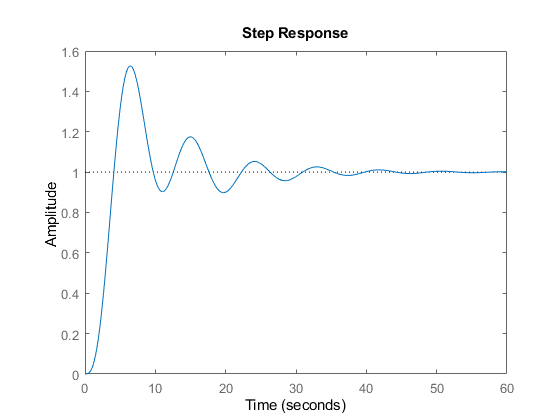

step(CL_pos2)

stepinfo(CL_pos2)

ans = struct with fields:
        RiseTime: 2.3240
    SettlingTime: 33.9532
     SettlingMin: 0.8984
     SettlingMax: 1.5262
       Overshoot: 52.6176
      Undershoot: 0
            Peak: 1.5262
        PeakTime: 6.4735


isstable(CL_pos2)

ans = logical
   1


### 2.3 - Linear Simulation

LS2 = sim('Part2_linsim',100);

Derivative of state '1' in block 'Part2_linsim/LTI System/Internal' at time 88.943549471638121 is not finite. The simulation will be stopped. There may be a singularity in the solution.  If not, try reducing the step size (either by reducing the fixed step size or by tightening the error tolerances)

plot(LS2.Alt.time,LS2.Alt.signals(1).values)
hold on
plot(LS2.Alt.time,LS2.Alt.signals(2).values)
hold off
title("Linear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")
plot(LS2.Pos.time,LS2.Pos.signals(1).values)
hold on
plot(LS2.Pos.time,LS2.Pos.signals(2).values)
hold off
title("Linear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 2.4 - Nonlinear Simulation

wind = 0;
variaciones = 0;
noise = 0;
NLS2 = sim('Part2_planarBicopter');

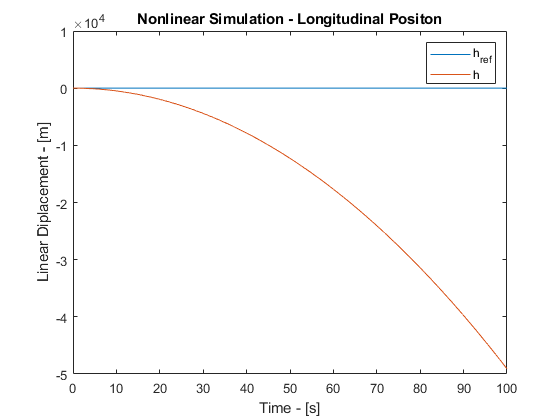

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

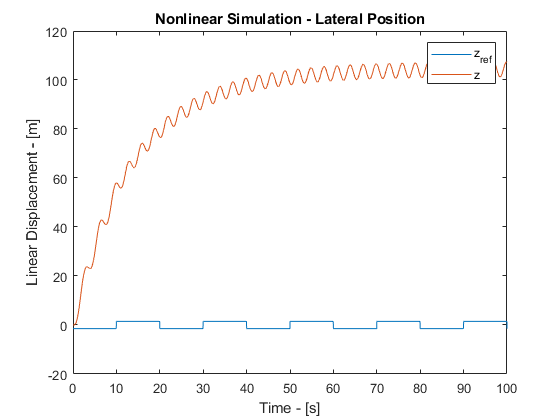

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 2.5 Comparison to Pole Placement

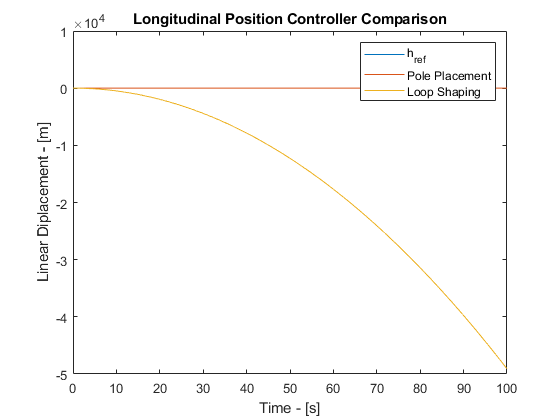

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS1.Alt.time,NLS1.Alt.signals(2).values(:,:))
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Longitudinal Position Controller Comparison")
legend("h_{ref}","Pole Placement","Loop Shaping")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

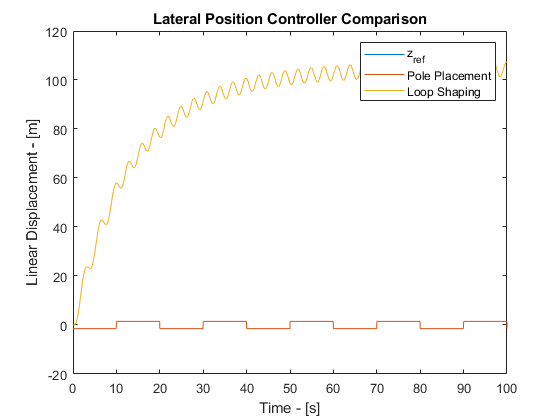

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS1.Pos.time,NLS1.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Lateral Position Controller Comparison")
legend("z_{ref}","Pole Placement","Loop Shaping")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 2.6 Addition of Noise

wind = 0;
variaciones = 0;
noise = 1e-6;
NLS2 = sim('Part2_planarBicopter');

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 2.7 Parameter Variation

wind = 0;
variaciones = 20;
noise = 0;
NLS2 = sim('Part2_planarBicopter');

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 2.8 Addition of Wind

wind = 1;
variaciones = 0;
noise = 0;
NLS2 = sim('Part2_planarBicopter');

plot(NLS2.Alt.time,NLS2.Alt.signals(1).values)
hold on
plot(NLS2.Alt.time,NLS2.Alt.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Longitudinal Positon")
legend("h_{ref}","h")
xlabel("Time - [s]")
ylabel("Linear Diplacement - [m]")

plot(NLS2.Pos.time,NLS2.Pos.signals(1).values)
hold on
plot(NLS2.Pos.time,NLS2.Pos.signals(2).values(:,:))
hold off
title("Nonlinear Simulation - Lateral Position")
legend("z_{ref}","z")
xlabel("Time - [s]")
ylabel("Linear Displacement - [m]")

### 2.9 Improvements